# Bernstein-Bezier curves

P = [0 1; 2 4; 6 3; 5 1; 0 1]           %(N+1)x2 double matrix of control points (CP) in R^2

P =      0     1
     2     4
     6     3
     5     1
     0     1


N = size (P,1) -1;                      % N = (number of points) - 1
syms t real                               
B = bernsteinMatrix (N,t);              % B is 1x(N+1) symbolic row

phi = simplify (B*P)'                   % B*CP is 1xd Bezier curve in R^d

$$phi = \left(\begin{array}{c} 4\,t\,\left(2\,t^{3}-7\,t^{2}+3\,t+2\right)\\ 12\,t^{3}-24\,t^{2}+12\,t+1 \end{array}\right)$$

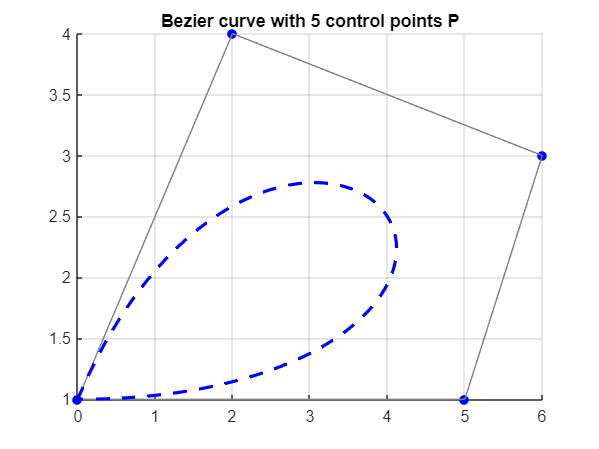


figure
hold on
scatter(P(:,1), P(:,2), 'b', "filled")  % draw the points
for i=1:N
    plot(P(i:i+1,1), P(i:i+1,2), "Color", 0.5*ones(1,3))  % draw the convex polygon
end
fplot (phi(1), phi(2) , [0, 1], "b--", LineWidth=2)   % draw the Bezier curve
title("Bezier curve with " + size(P,1)+ " control points P")
grid on

Adding more control points points, the Bezier curve will be closer and closer:

Q = [0 1; 3/4 9/8+1; 1.5 9/4+1; 2 4; 4 3.5; 5 -5/4+4.5; 6 3; 5.4 2*5.4-9; 5.8 2*5.8-9; 5 1; 0 1]

Q =          0    1.0000
    0.7500    2.1250
    1.5000    3.2500
    2.0000    4.0000
    4.0000    3.5000
    5.0000    3.2500
    6.0000    3.0000
    5.4000    1.8000
    5.8000    2.6000
    5.0000    1.0000


figure
BezierQ = plotBezier(Q, "r", "-")

$$BezierQ = \left(\begin{array}{c} \frac{t\,\left(446\,t^{9}-2201\,t^{8}+4914\,t^{7}-6684\,t^{6}+5880\,t^{5}-3150\,t^{4}+840\,t^{3}-60\,t^{2}+15\right)}{2}\\ 84\,t^{10}-\frac{159\,t^{9}}{4}-621\,t^{8}+1461\,t^{7}-1470\,t^{6}+\frac{1449\,t^{5}}{2}-105\,t^{4}-45\,t^{3}+\frac{45\,t}{4}+1 \end{array}\right)$$

hold on
BezierP = plotBezier(P, "b", "--")

$$BezierP = \left(\begin{array}{c} 4\,t\,\left(2\,t^{3}-7\,t^{2}+3\,t+2\right)\\ 12\,t^{3}-24\,t^{2}+12\,t+1 \end{array}\right)$$

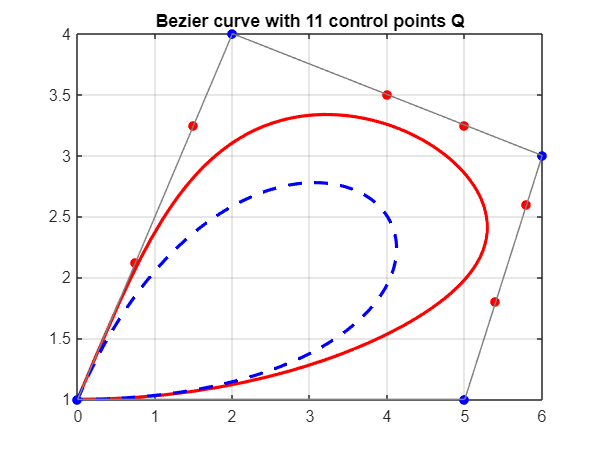

title("Bezier curve with " + size(Q,1)+ " control points Q")
grid on

function  bezierCurve = plotBezier(P, color, style)
syms t real
N = size(P,1)-1;
B = bernsteinMatrix(N,t);
bezierCurve = simplify(B*P)';
fplot(bezierCurve(1), bezierCurve(2), [0, 1], LineWidth=2, Color=color, LineStyle=style) % plot Bezier
hold on
scatter(P(:,1), P(:,2),[], color,'filled')  % plot the points
for i=1:N
    plot(P(i:i+1,1), P(i:i+1,2), "Color", 0.5*ones(1,3))  % plot the external polygon
end
end